# **Training CN-vs-MCIc**

Due to memory (RAM) and computational power limits in this code instead of converting each MRI in 100 pictures, we are going to extract just 3 slices for each MRI, train on 2 fold instead of 20 and not performing any data augmentation.

### **Code structure:**

**1) Define the network (Transfer learning from AlexNet)**

**2) Set training parameters**

**3) Load the Dataset:**

- Load .mat files

- Concatenate CN_training, CN_testing,... in a single cell array

- Transform the 238 MRI images into 714 (=238*3) 227x227x3 Images (~1GB)

**4) Cross Fold Validation (for 2 fold):**

- Find patterns to use for Testing (index==fold) and Training (index!=fold) and Split the dataset in Training and Testing for this fold

- Shuffle the trainingImages (and respectively their labels)

- Train

- Save the trained model

- Validate on test set

- Compute Metrics

## **Problem parameters**

% Type of problem
problem="CN_vs_MCIc";
%problem="CN_vs_AD";
%problem="MCInc_vs_MCIc";

% Axis
axis="x-axis";
%axis="y-axis";

axis = "x-axis"

%axis="z-axis";


%---------------------------------------------------------------
time=datestr(now,"yyyy-mm-dd-HH:MM"); %Save execution time

% Where to save this execution files
directory="../TrainedModels/"+problem+"/"+axis+"/"+time+"/";


directory = "../TrainedModels/CN_vs_MCIc/x-axis/2019-03-30-11:46"

## **1) Define the Network**

by modifing the last 3 layers of AlexNet

clear all
warning off

siz=[227 227]; % input size of the CNN (AlexNet)

net = alexnet;
layers=net.Layers;
layers(end-2)=fullyConnectedLayer(2,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20);
layers(end-1)=softmaxLayer;
layers(end)=classificationLayer;

## **2) Set training parameters**

miniBatchSize = 30;
learningRate = 1e-4;
optimizer='sgdm';
options=trainingOptions(optimizer,...
    "MiniBatchSize",miniBatchSize,...
    "InitialLearnRate",learningRate,...
    'MaxEpochs',20,...
    "Verbose",false,...
    "Plots","training-progress");

## **3) Load the Dataset**

**Load CN.mat and MCIc.mat**

**Concatenate CN_training, CN_testing, MCIc_training, MCIc_testing in a single cell array**

% Concatenate all dataset files in a single cell array
load("../Dataset/CN.mat")
load("../Dataset/MCIc.mat")
dataset=cat(1,CN_training,CN_testing,MCIc_training,MCIc_testing);

% Create label array
lengthClass1=(length(CN_training)+length(CN_testing));
lengthClass2=(length(MCIc_training)+length(MCIc_testing));
mriLabel(1:lengthClass1)=1; %Cognitive Normal = 1
mriLabel(lengthClass1:lengthClass1+lengthClass2)=2;

clear CN_training CN_testing MCIc_training MCIc_testing lengthClass1 lengthClass2

**Transform the 238 MRI images into 714 (=238*3) 227x227x3 Images (~1GB)**

Images=[];
label=[]; % labels of classes 
labelID=[]; % labels of ID
tmpTR=1;
for i=1:length(mriLabel)
    % Extract single MRI
    IMG=dataset{i};

    % Transform MRI picture into 3 images 227x227x3
    IMG=mriToCNN(IMG,siz);
    Images(:,:,:,tmpTR:tmpTR+size(IMG,4)-1)=IMG;

    % Return label vector with labels of the new 3 pictures
    class=mriLabel(i);
    label(tmpTR:tmpTR+size(IMG,4)-1)=class;

    % Save single person's ID
    labelID(tmpTR:tmpTR+size(IMG,4)-1)=i;

    tmpTR=tmpTR+size(IMG,4); %Increasing counter by 3

    clear IMG;
end

clear dataset mriLabel class tmpTR

## **4) Cross fold validation (2 fold)**

for fold=1:2

**            Find patterns to use for Testing (index==fold) and Training (index!=fold)**

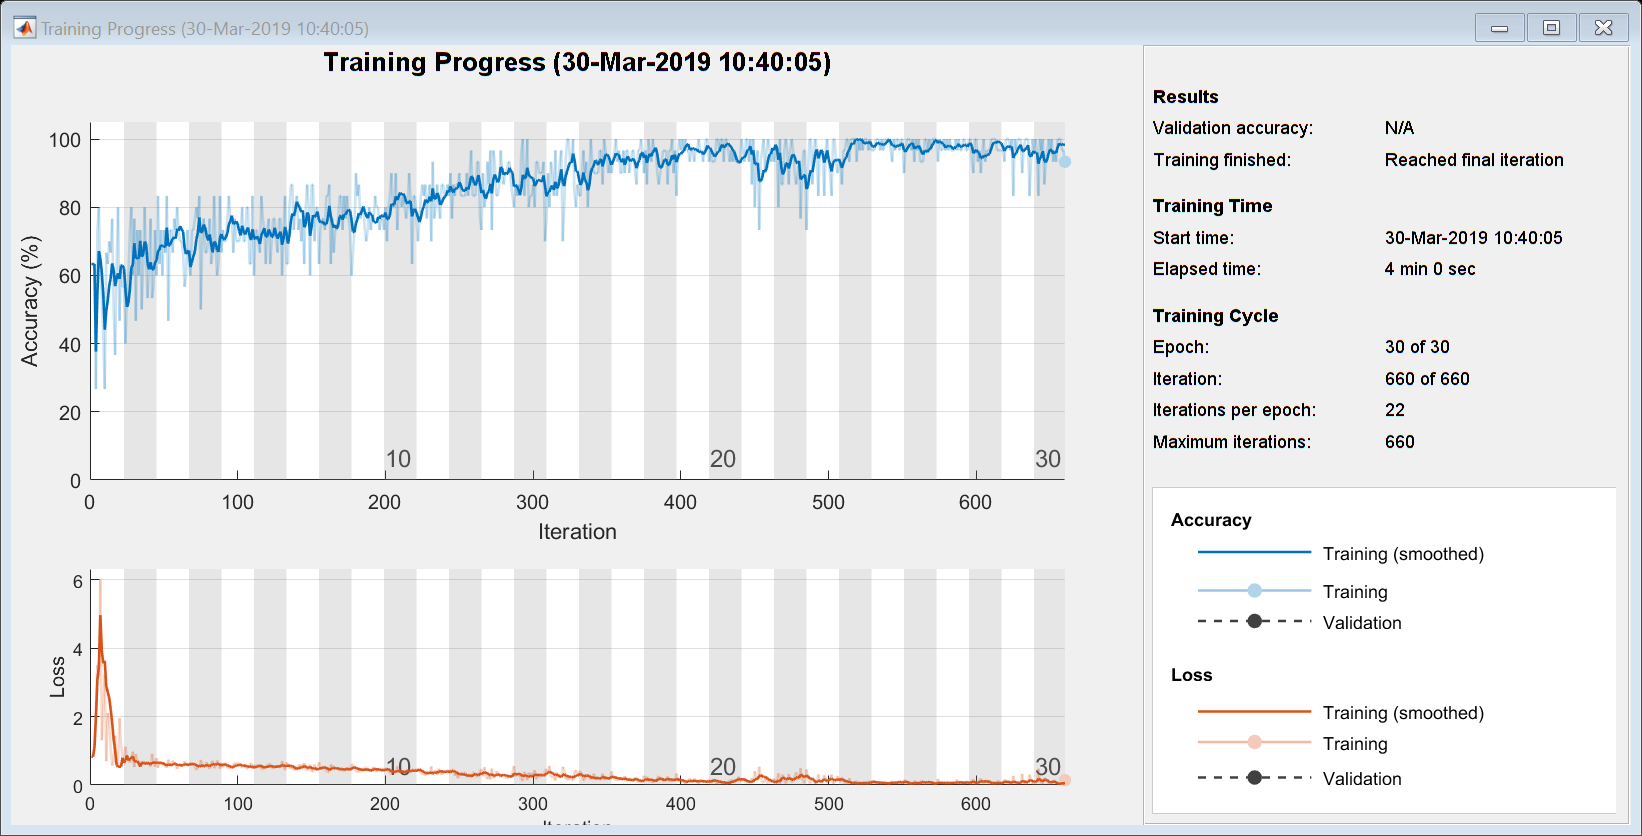

    % Split the dataset in Training and Testing for this fold    
    load("../Dataset/indices_CN-vs-MCIc.mat")
    
    trainingIndices=double([Indices~=fold])';
    trainingIndices=trainingIndices.*[1:length(trainingIndices)];
    trainingIndices=trainingIndices(trainingIndices~=0);
    trainingIndices=double(ismember(labelID,trainingIndices));
    trainingIndices=trainingIndices.*[1:length(trainingIndices)];
    trainingIndices=trainingIndices(trainingIndices~=0);
    
    trainingImages=Images(:,:,:,trainingIndices);
    trainingLabel=label(:,trainingIndices);
    trainingID=labelID(:,trainingIndices);
    
    testingIndices=double([Indices==fold])';
    testingIndices=testingIndices.*[1:length(testingIndices)];
    testingIndices=testingIndices(testingIndices~=0);
    testingIndices=ismember(labelID,testingIndices);
    testingIndices=testingIndices.*[1:length(testingIndices)];

    testingIndices=testingIndices(testingIndices~=0);
    
    testImages=Images(:,:,:,testingIndices);
    testLabel=label(:,testingIndices);
    testID=labelID(:,testingIndices);
    
    clear indices_CN-vs-MCIc.mat trainingIndices testingIndices

   **         Shuffle the trainingImages (and respectively their labels)**

    indicesVector=[1:length(trainingLabel)]; % indices from 1 to trainingImages length (~678)
    indicesVector=indicesVector(randperm(length(indicesVector))); % Shuffle vector of indices
    
    trainingImages=trainingImages(:,:,:,indicesVector);
    trainingLabel=trainingLabel(:,indicesVector);
    trainingID=trainingID(:,indicesVector);

            **Train**

    valueset = [1:2];
    Y=categorical(trainingLabel',valueset);
    
    [trainedNet,info]=trainNetwork(trainingImages,Y,layers,options);

**            Save the trained model**

    save(directory+"trainedModel"+fold+".mat", "trainedNet");
    save(directory+"trainingInfo"+fold+".mat","info");

            **Validation**

    predictions = classify(trainedNet,testImages);

**            Metrics**

    predictions=double(predictions);

    TP(fold)= sum(and((predictions==2)',testLabel==2))
    TN(fold)= sum(and((predictions==1)',testLabel==1))
    FP(fold)= sum(and((predictions==2)',testLabel==1))
    FN(fold)= sum(and((predictions==1)',testLabel==2))
    
    precision(fold)= TP(fold)/(TP(fold)+FP(fold))
    recall(fold)=TP(fold)/(TP(fold)+FN(fold))
    f1(fold)=2*(precision(fold)*recall(fold))/(precision(fold)+recall(fold))
    specificity(fold)=FP(fold)/(FP(fold)+TN(fold))
    accuracy(fold)=(TP(fold)+TN(fold))/(TP(fold)+TN(fold)+FP(fold)+FN(fold))

    confusionchart(testLabel,predictions)
    
    
    
end %End of cross fold validation

### **Save metrics**

save(directory+"Metrics.mat","TP","TN","FP","FN","precision","recall","f1","specificity","accuracy")



function [IMG]=mriToCNN(IMG,siz) 
    % Removing NaN values
    IMG(find(isnan(IMG)))=0;
    
    % Extract 3 slices in sequence from the middle
    % Resize each 121x145 slice to 227x227
    clear RID
    for livello=1:3
        RID(:,:,1,livello)=imresize(IMG(:,:,livello+60),[siz(1) siz(2)]);
        RID(:,:,2,livello)=imresize(IMG(:,:,livello+60),[siz(1) siz(2)]);
        RID(:,:,3,livello)=imresize(IMG(:,:,livello+60),[siz(1) siz(2)]);
    end
    
    clear IMG
    
    % Normalize values
    M=max(RID(:));
    IMG=floor(RID.*(255/M));
    
    clear RID
end